BB = importdata('./ZebraFish/groundtruth_rect.txt');
Idir = dir('./ZebraFish/img/*.jpg');

descriptores = []; 

%% Entrenament del classificador

nf = size(Idir); % nombre total de fitxers imatges
for i = 1:min(600, nf)
    boundbox = BB(i,:);
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    image = rgb2gray(imread(filename));

    puntosClave = selectStrongest(detectSURFFeatures(image), 100);

    puntosClaveFondo = puntosClave( puntosClave.Location(:,1) < boundbox(2) |  ...
        puntosClave.Location(:,1) > (boundbox(2) + boundbox(4) ) | ...
        puntosClave.Location(:,2) < boundbox(3) | ...
        puntosClave.Location(:,2) > (boundbox(3) + boundbox(5) ));

    puntosClaveObjeto = puntosClave( puntosClave.Location(:,1) >= boundbox(2) &  ...
        puntosClave.Location(:,1) <= (boundbox(2) + boundbox(4) ) & ...
        puntosClave.Location(:,2) >= boundbox(3) & ...
        puntosClave.Location(:,2) <= (boundbox(3) + boundbox(5) ));
    
    [descriptoresFondo, ~] = extractFeatures(image, puntosClaveFondo);
    [descriptoresObjeto, ~] = extractFeatures(image, puntosClaveObjeto);
    [f, ~] = size(descriptoresFondo);
    descriptoresFondo = [descriptoresFondo, zeros(1,f)'];

    [o, ~] = size(descriptoresObjeto);
    descriptoresObjeto = [descriptoresObjeto, ones(1,o)'];

    descriptores = [descriptores; descriptoresFondo; descriptoresObjeto];
end


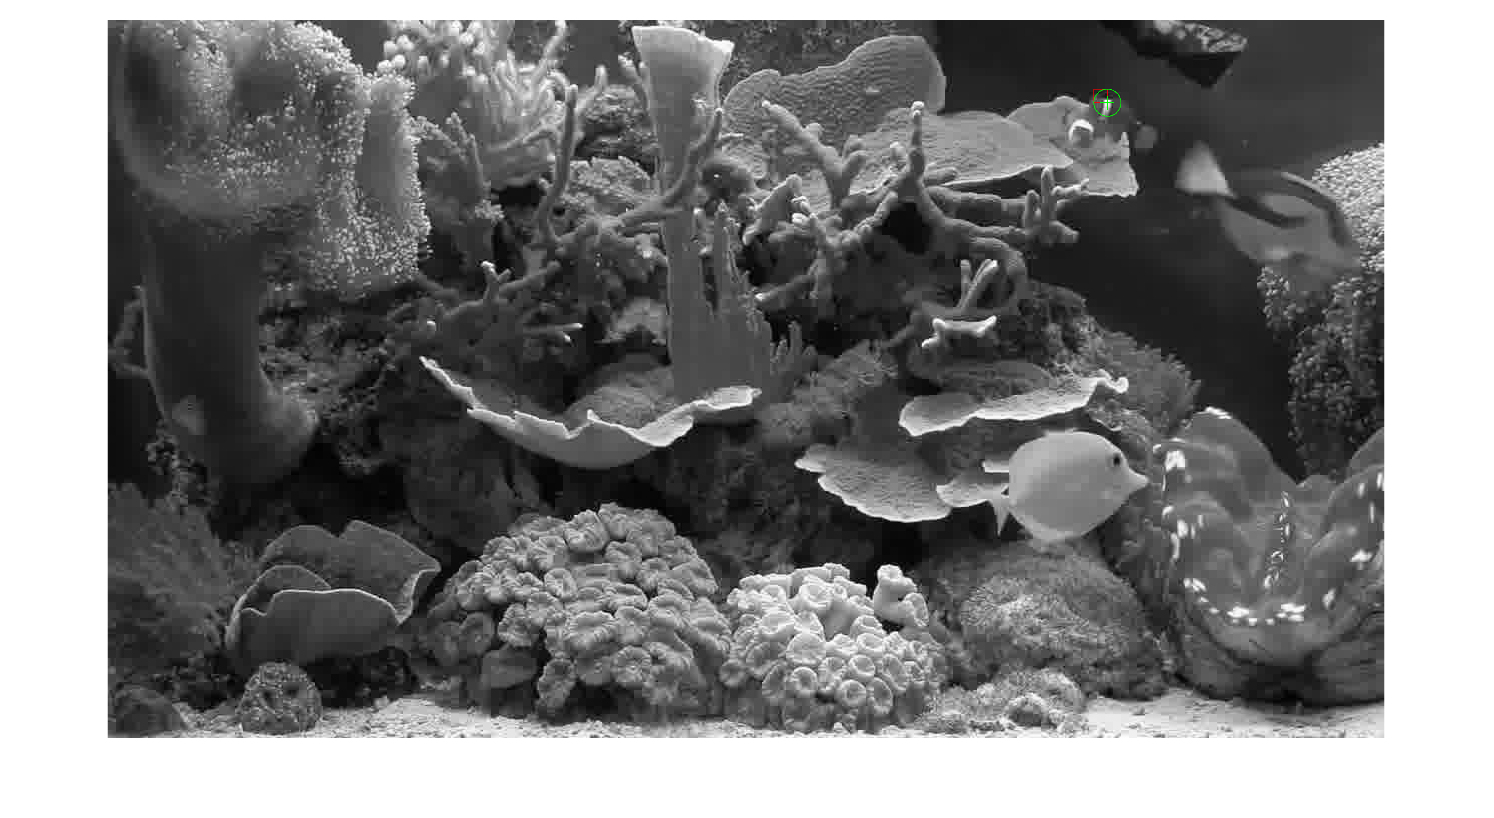

%% Detecció de l'objecte

iou = [];
figure
%hold on % mantenim sempre oberta la mateixa figura
nf = size(Idir); % nombre total de fitxers imatges
for i = 1:min(35, nf)
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);            
    image = rgb2gray(imread(filename));

    puntos = selectStrongest(detectSURFFeatures(image), 120);
    

    [features, ~] = extractFeatures(image, puntos);

    ynew = trainedModel.predictFcn(features);
    
    puntosObj = puntos(ynew == 1, :);
    
    [x, y, w, h] = calcularBB(puntosObj.Location, puntosObj.Scale);

    overlapRatio = bboxOverlapRatio([x, y, w, h],BB(i,2:5));

    iou = [iou, overlapRatio];

    imshow(image);
    hold on
    rectangle('Position',[x, y, w, h],'EdgeColor','red');
    drawnow
    plot(puntosObj);
    hold off

    %descriptores = [descriptores; descriptoresFondo; descriptoresObjeto];
end

iou

iou =     0.6640    0.6610    0.3246    0.2155    0.2535    0.3002    0.1435    0.0419    0.0419    0.0382    0.0364    0.0382    0.0382    0.0601    0.1527    0.0716    0.7198    0.0281    0.6617    0.5784    0.5763    0.0736    0.2177    0.1968    0.2333    0.2145    0.1192    0.0846    0.0252         0    0.0414    0.0580    0.0836    0.6699    0.0209


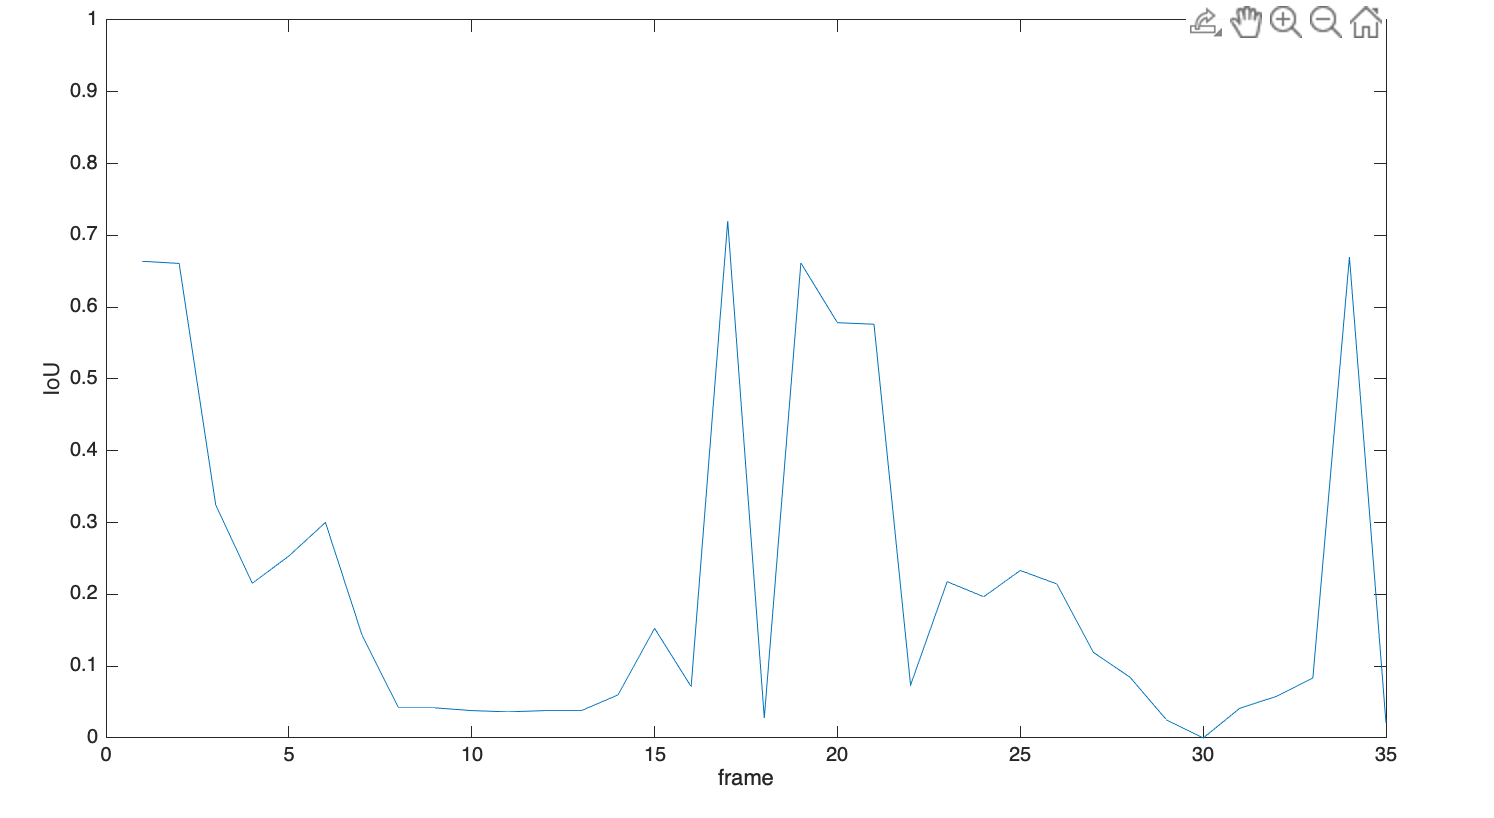

plot(1:35, iou)
ylim([0, 1])
xlabel('frame')
ylabel('IoU');

function [x, y, w, h] = calcularBB(puntos, scale)
    [x2, idx] = min(puntos(:,1));
    if scale(idx) > 4
        x = x2-3*scale(idx);
    else
        x = x2-6*scale(idx);
    end
    [y2, idx] = min(puntos(:,2));
    if scale(idx) > 4
        y = y2-3*scale(idx);
    else
        y = y2-6*scale(idx);
    end
    [w, idx] = max(puntos(:,1));
    w = abs(x - w);
    [h, idx] = max(puntos(:,2));
    h = abs(y - h);
end
